# Industrial Symbiosis in Subsea Oil and Gas Production

### Dinesh Krishnamoorthy, Department of Chemical Engineering, NTNU

* e-mail: dinesh.krishnamoorthy@ntnu.no*

Two companies operate 3 gas-lifted wells each. The two companies share the processing facilities. The lift gas is a shared resource that must be optimall allocated between the two companies. The processing capacity also has a limited gas processing capacity. 

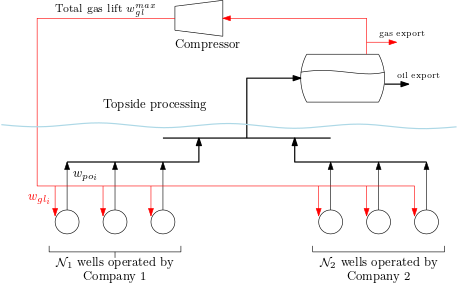

The goal is to optimize the overall system with limited information sharing. 

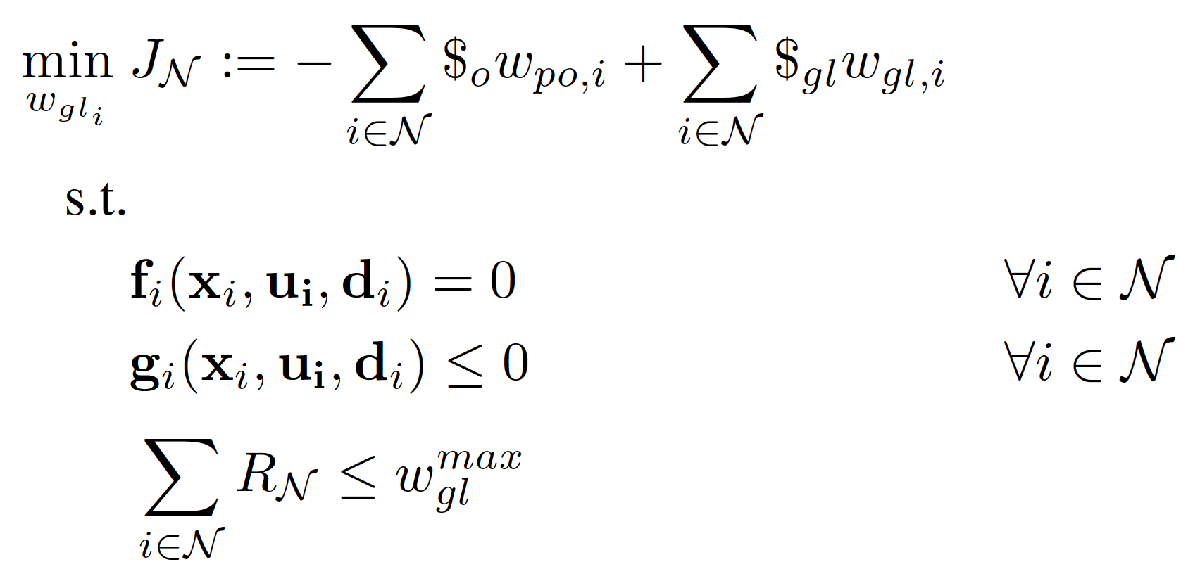

*The following code uses CasADi v3.5.1. *

clear
clc
import casadi.*

% Setup simulation Parameters

TotalTime = 24;  % [h]  Total time of simulation
TimeRTO   = 300; % [s]  Sampling time of  RTO
TimeMPC   = 60;  % [s]  Sampling time for the setpoint tracking NMPC
TimeEKF   = 1;   % [s]
Prediction_Horizon = 2; %[h]  % Prediction Horizon for NMPC
nIter = TotalTime*3600/TimeRTO;

global pO pGL % Prices
pO = 1;
pGL = 0.3;

Load the well parameters operated by the two companies

par1 = WellParameters_Company1;        % Load parameters for company 1
par2 = WellParameters_Company2;        % Load parameters for company 2


Now load the Plant simulator, which consists of the overall system (company 1 + company 2)

par.tf = TimeEKF; % Simulator integration time [s]
[F,xf,par] = PlantSimulatorModel(par.tf,par1,par2);

% Initial conditions for the simulator
dhat1 = [par1.GOR;20];
dhat2 = [par2.GOR;20];
u01 = [1;1;1];
u02 = [1;1;1];
xf1 = xf(par.ind1);
xf2 = xf(par.ind2);

### Distributed Hybrid RTO framework

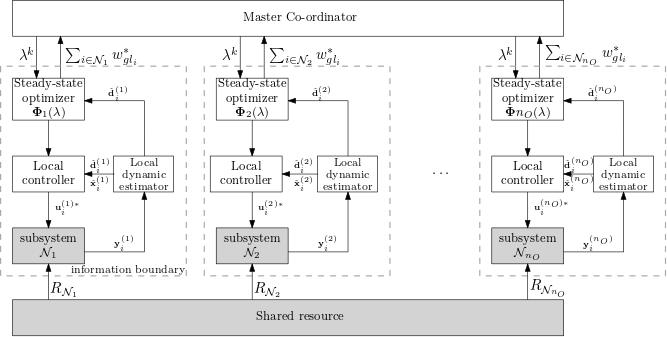

The proposed distributed Hybrid RTO has 4 components

- Decentralized Estimator block for each company

- Decentralized setpoint tracking controller for each company

- Distributed steady-state RTO using transient measurements for each company

- A master co-ordinator that updates and broadcasts the shadow prices - This is the only component that is common to all the companies. The first three blocks are not shared among the different companies. 

Setup the individual ODE model from each company that is used for optimization and control. 

[sys1,~,f1,par1] = GasLiftModel(par1); % Load model for company 1
[sys2,~,f2,par2] = GasLiftModel(par2); % Load model for company 2
[sys3,par3] = Node3;

Setup the decentralized Augmented extended Kalman filter for combined state and parameter estimation for each company. 

The EKF estimates the parameters (GOR and manifold pressure in this case) which is used in the steady-state model in the RTO layer. The state and parameter estimates are also used for state feedback in the setpoint tracking NMPC. 

EKF1 = prepareAEKF(sys1,par.tf(1)); % EKF for company 1
EKF2 = prepareAEKF(sys2,par.tf(2)); % EKF for company 2

xk_hat1 = vertcat(xf1,dhat1);
xhat1 = xf1;
xhat2 = xf2;
Pk1 = EKF1.Pk;

xk_hat2 = vertcat(xf2,dhat2);
Pk2 = EKF2.Pk;

Define the coupling constraints. In our case it is the total gas lift resource and total gas processing capacity constraints. 

% ---------- COUPLING CONSTRAINTS --------------

sys1.g = vertcat(sum(sys1.u),...
    sum(sys1.y(3*par1.n_w+1:4*par1.n_w)));  % company 1

sys2.g = vertcat(sum(sys2.u),...
    sum(sys2.y(3*par1.n_w+1:4*par1.n_w)));  % company 2

sys3.g = sys3.x;  % Node 3

% ----------- Steady-state RTO setup -----------

[solver1,par1] = AugmentedLagrangian_sharing(sys1,par1);
[solver2,par2] = AugmentedLagrangian_sharing(sys2,par2);
[solver3,par3] = AugmentedLagrangian_sharing(sys3,par3);

w01 = vertcat(xf1,ones(3,1));
w02 = vertcat(xf2,ones(3,1));
w03 = par3.dx0;

Setup the setpoint tracking NMPC control for each company

%--------- Setpoint tracking NMPC setup --------

par.Horizon_Samples = Prediction_Horizon*3600/TimeRTO;
par1.Horizon_Samples = par.Horizon_Samples;
par2.Horizon_Samples = par.Horizon_Samples;

[MPCsolver1,MPC1] = SetpointNMPC(sys1,par1);
[MPCsolver2,MPC2] = SetpointNMPC(sys2,par2);

Define initial conditions before starting the simulations

lambda = [1;0]; % Lagrange multipliers
lambda0 = [0;0];
dlambda = 1;

rho = 0.05;  % Augmented Lagrangian

toll = 1e-4;    % Tolerance
MaxIt = 200;    % Maximum number of iterations

g1_opt = vertcat(4,12);
g2_opt = vertcat(4,12);
g3_opt = vertcat(-8,-24);

elapsedRTO1 = zeros(MaxIt,1);
elapsedRTO2 = zeros(MaxIt,1);
elapsedRTO3 = zeros(MaxIt,1);

#### Closed-loop simulation

Now that the system is setup, we can now simulate the system 

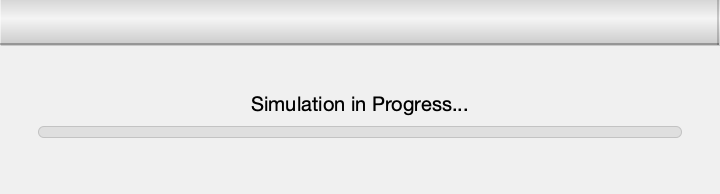

 


h = waitbar(0,'Simulation in Progress...');

for sim_k = 1:nIter
    waitbar(sim_k /nIter)

#### Distributed RTO  using ADMM 

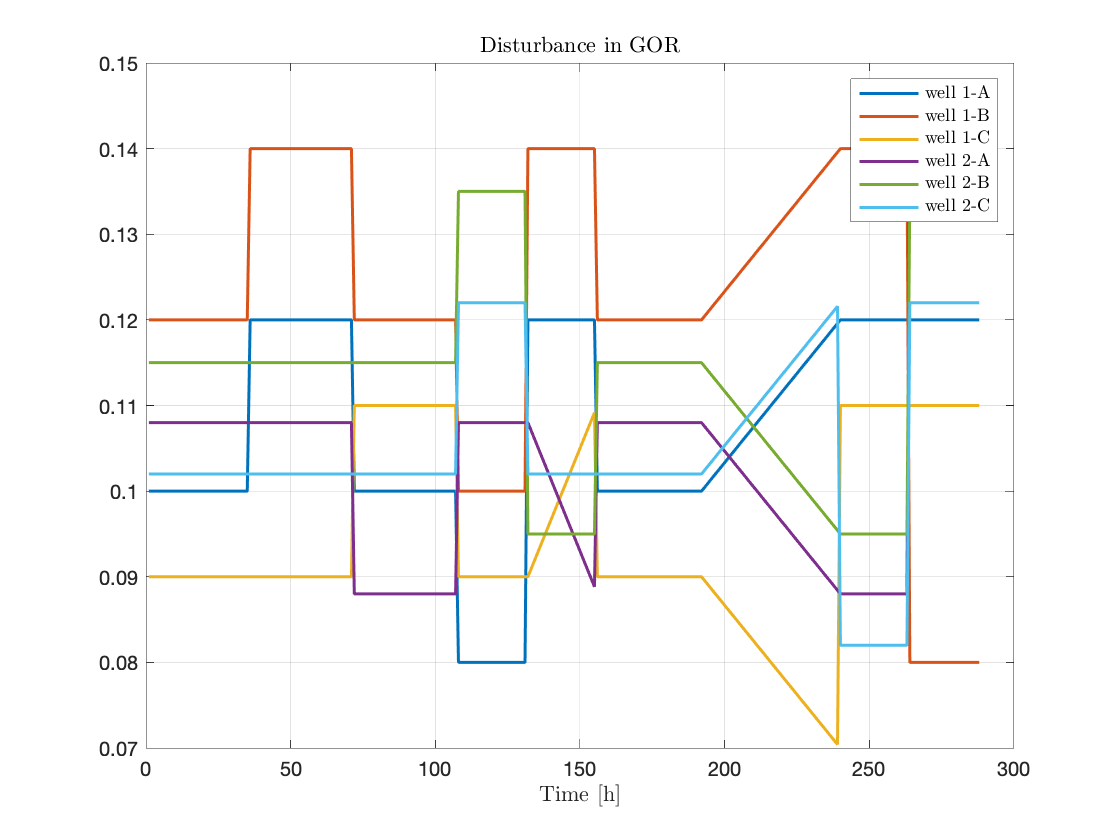

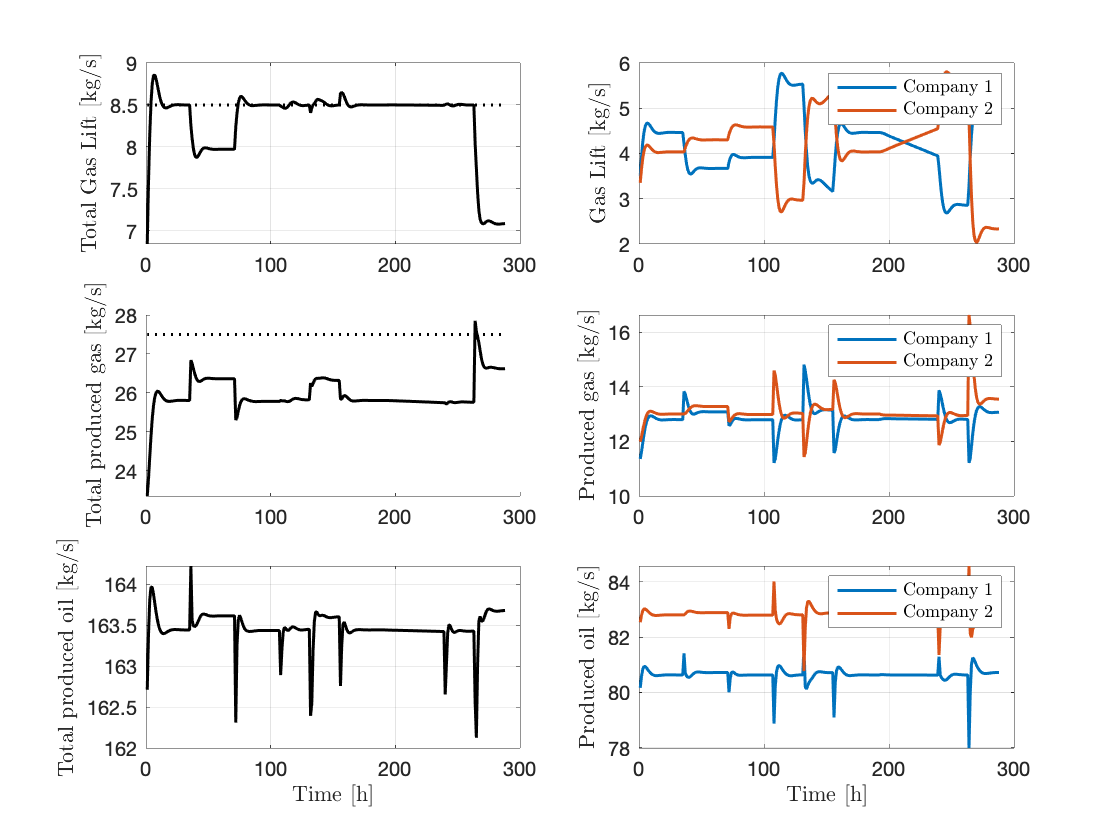

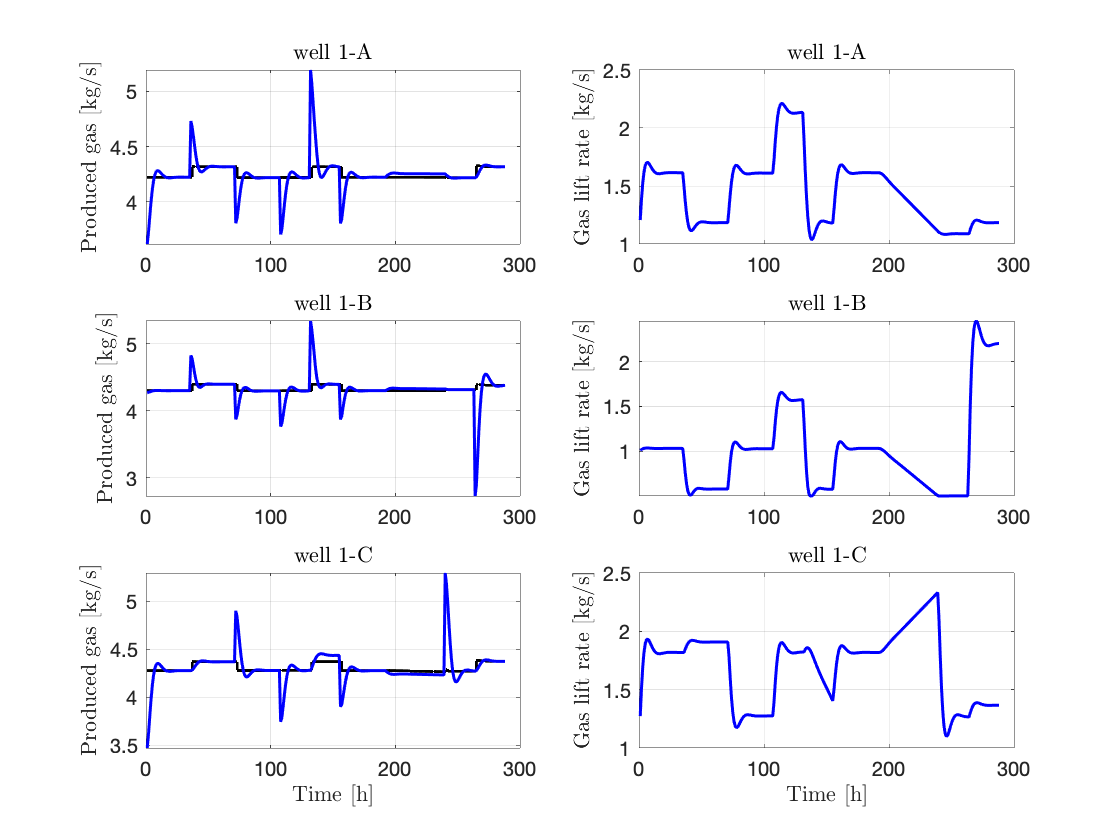

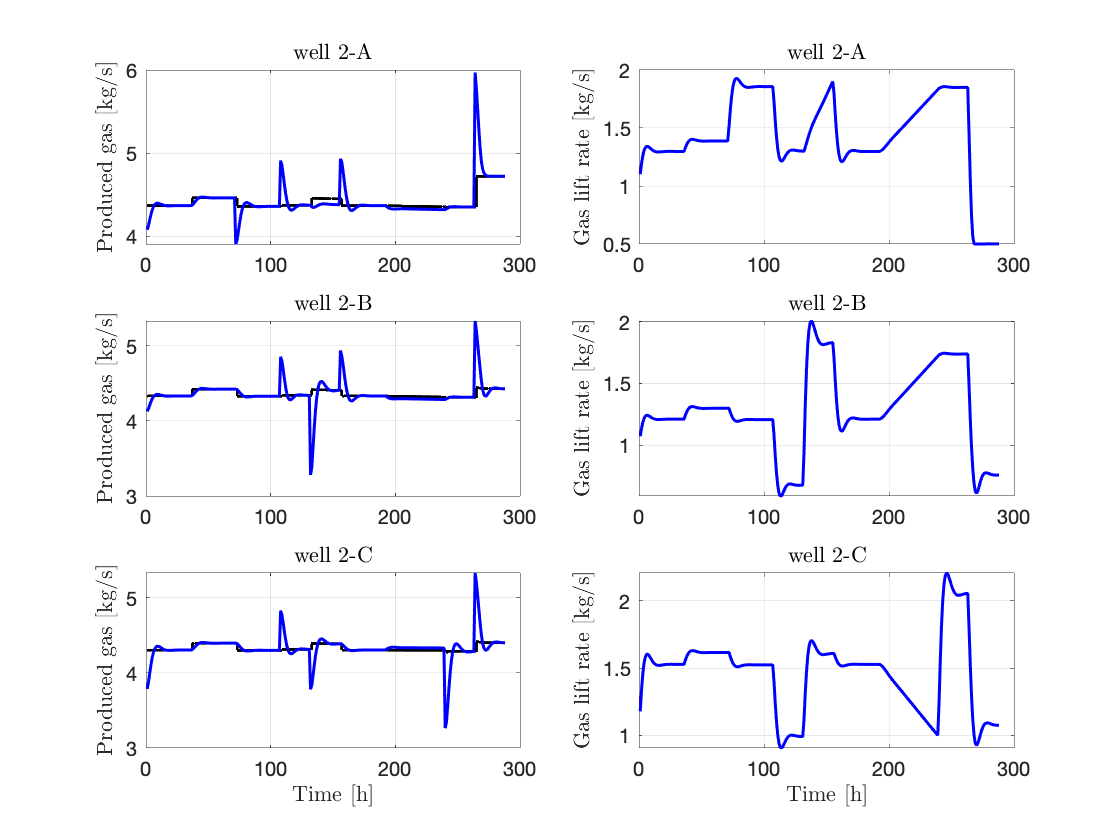

    
    % Reset dual residual and ADMM counter
    dlambda = 1;
    ADMM_iter = 0;
    
    while (max(abs(dlambda)) > toll) && ADMM_iter < MaxIt
        
        ADMM_iter = ADMM_iter +1;
        
        g_avg = (g1_opt + g2_opt + g3_opt)/3;
        
        % ---------------- RTO company 1 ------------------
        
        nlp_par1 = vertcat(dhat1,lambda,rho,g1_opt,g_avg);
        
        tic
        sol1 = solver1('x0',w01,'p',nlp_par1, ...
            'lbx',par1.lbw,'ubx',par1.ubw,'lbg',par1.lbg,'ubg',par1.ubg);
        elapsedRTO1(ADMM_iter) = toc;
        
        flag1 = solver1.stats();
        assert(flag1.success == 1, 'Error! RTO for subsystem 1 failed.')
        
        % Get Optimal of SP1 at current price (lambda)
        w01 = full(sol1.x);
        u1_opt = w01(10:12);
        y1_opt = sys1.y_model( w01(1:9),vertcat(u1_opt,dhat1));
        w_pg1_opt = full(y1_opt(3*par1.n_w+1:4*par1.n_w));
        
        % Update coupling constraint
        g1_opt = vertcat(sum(u1_opt),sum(w_pg1_opt));
        
        
        % ---------------- RTO Company 2 ------------------
        
        nlp_par2 = vertcat(dhat2,lambda,rho,g2_opt,g_avg);
        

        tic
        sol2 = solver2('x0',w02,'p',nlp_par2, ...
            'lbx',par2.lbw,'ubx',par2.ubw,'lbg',par2.lbg,'ubg',par2.ubg);
        elapsedRTO2(ADMM_iter) = toc;
        
        flag2 = solver2.stats();
        assert(flag2.success == 1, 'Error! RTO for subsystem 2 failed.')
        
        % Get Optimal of SP2 at current price (lambda)
        w02 = full(sol2.x);
        u2_opt = w02(10:12);
        y2_opt = sys2.y_model(w02(1:9),vertcat(u2_opt,dhat2));
        w_pg2_opt = full(y2_opt(3*par2.n_w+1:4*par2.n_w));
        
        % Update Coupling constraint
        g2_opt = vertcat(sum(u2_opt),sum(w_pg2_opt));
        
        
        % -------------------- Node 3 ----------------------
        
        nlp_par3 = vertcat(lambda,rho,g3_opt,g_avg);
        
        tic
        sol3 = solver3('x0',w03,'p',nlp_par3, ...
            'lbx',par3.lbw,'ubx',par3.ubw,'lbg',par3.lbg,'ubg',par3.ubg);
        elapsedRTO3(ADMM_iter) = toc;
        
        flag3 = solver3.stats();
        assert(flag3.success == 1, 'Error! Node 3 failed.')
        
        % Get Optimal of SP3 at current price (lambda)
        g3_opt = full(sol3.x);
        w03 = g3_opt;
        
        % ---------------- Master Co-ordinator ---------------------
        
        primal_residual = g1_opt + g2_opt + g3_opt ;
        
        % Update Lagrange multiplier
        lambda = max(0,lambda + rho*primal_residual);
        
        dlambda = lambda - lambda0;
        lambda0 = lambda;
        
    end
    
    
    % Save optimal setpoints computed by RTO layer
    data.data1.w_pg_sp(:,sim_k) = w_pg1_opt;
    data.data2.w_pg_sp(:,sim_k) = w_pg2_opt;
    
    % Save other interesting variables
    data.data1.u_opt(:,sim_k) = u1_opt;
    data.data2.u_opt(:,sim_k) = u2_opt;
    
    % Save computation time and no. of iterations
    data.data1.elapsedRTO(sim_k) = mean(elapsedRTO1);
    data.data2.elapsedRTO(sim_k) = mean(elapsedRTO2);
    data.elapsedRTO(sim_k) = mean(elapsedRTO3);
    data.ADMM_iter(sim_k)  = ADMM_iter;
    
    if ADMM_iter >= MaxIt
        warning(['Time step ' num2str(sim_k) ': Maximum number of iterations reached'])
    end

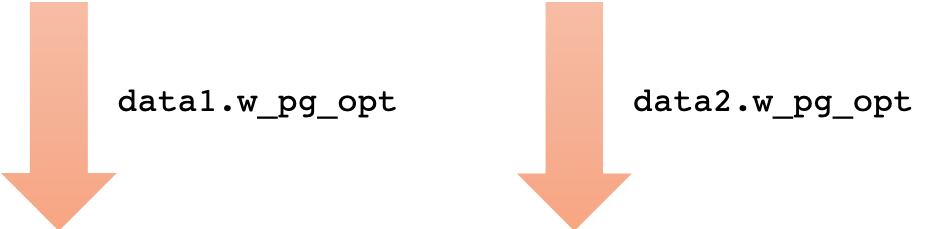

#### Setpoint tracking MPC

    for iSP = 1:TimeRTO/TimeMPC
        
        % --------- MPC for Company 1 ----------
        MPC_par1 = vertcat(w_pg1_opt,dhat1,xhat1,u01);
        
        tic
        solNMPC1   = MPCsolver1('x0',MPC1.w0,'p',MPC_par1,'lbx',MPC1.lbw,...
            'ubx',MPC1.ubw,'lbg',MPC1.lbg,'ubg',MPC1.ubg);
        data.data1.elapsedMPC(sim_k) = toc;
        
        MPC1.w0     = full(solNMPC1.x);
        u01 = MPC1.w0(10:12);
        
        % --------- MPC for Company 2 ----------
        MPC_par2 = vertcat(w_pg2_opt,dhat2,xhat2,u02);
        
        tic
        solNMPC2   = MPCsolver2('x0',MPC2.w0,'p',MPC_par2,'lbx',MPC2.lbw,...
            'ubx',MPC2.ubw,'lbg',MPC2.lbg,'ubg',MPC2.ubg);
        data.data2.elapsedMPC(sim_k) = toc;
        
        MPC2.w0 =  full(solNMPC2.x);
        u02 = MPC2.w0(10:12);
        
        u_in = [u01;u02]; % Optimal inputs computed by setpoint tracking control

#### 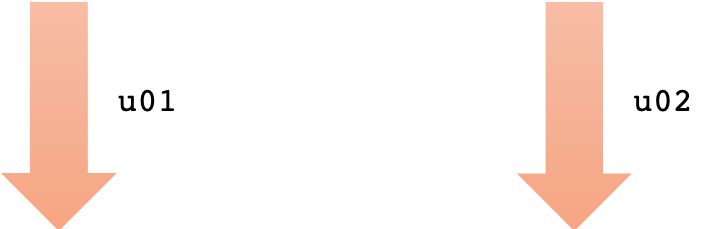

#### Plant simulation 

        [GOR_real,Constraints] = Disturbances(sim_k,nIter,par); % predetermined disturbance sequence used for simulation
        
        for iSim = 1:TimeMPC
            
            % Simulator using IDAS integrator every second
            Fk = F('x0',xf,'p',vertcat(u_in,GOR_real,20));
            
            % Get solution
            xf = full(Fk.xf);
            J_real(:,1) = full(Fk.qf);
            
            xf1 = xf(par.ind1);
            xf2 = xf(par.ind2);
            dist1 = vertcat(GOR_real(1:par1.n_w),20);
            dist2 = vertcat(GOR_real(par1.n_w+1:par1.n_w+par2.n_w),20);
            data1.y = full(sys1.y_model(xf1,vertcat(u01,dist1)));
            data2.y = full(sys2.y_model(xf2,vertcat(u02,dist2)));
            

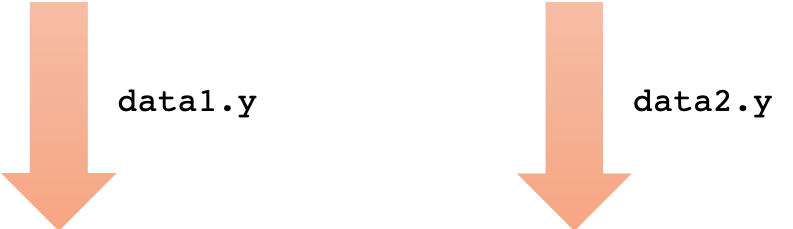

#### State and parameter estimation using Extended Kalman filter

            %% State and Parameter estimation using EKF
            
            [xk_hat1,Pk1] = EKF_estimation(EKF1,data1.y,u01,xk_hat1,Pk1);
            xhat1 = xk_hat1(1:3*par1.n_w);
            dhat1 = xk_hat1(3*par1.n_w+1:4*par1.n_w+1);
            
            [xk_hat2,Pk2] = EKF_estimation(EKF2,data2.y,u02,xk_hat2,Pk2);
            xhat2 = xk_hat2(1:3*par2.n_w);
            dhat2 = xk_hat2(3*par2.n_w+1:4*par2.n_w+1);
            
        end
        

                                                                                                                                                               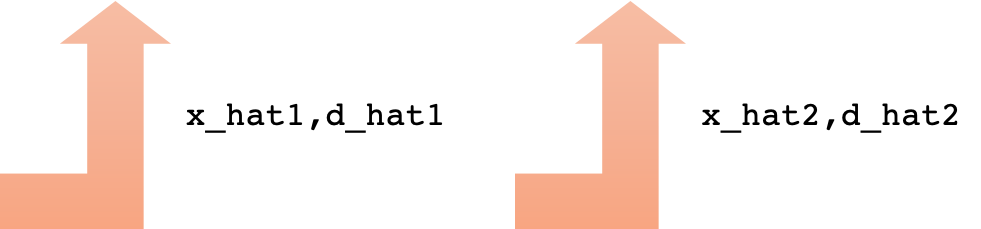

Save and plot results

    end
    
    data.data1.u(:,sim_k) = u01;
    data.data1.w_pg(:,sim_k) = data.data1.y(10:12);
    data.data1.w_po(:,sim_k) = data.data1.y(7:9);
    data.data1.d(:,sim_k) = dist1;
    data.data1.dhat(:,sim_k) = dhat1;
    data.data1.y(:,sim_k) = data1.y;
    
    data.data2.u(:,sim_k) = u02;
    data.data2.w_pg(:,sim_k) = data.data2.y(10:12);
    data.data2.w_po(:,sim_k) = data.data2.y(7:9);
    data.data2.d(:,sim_k) = dist2;
    data.data2.dhat(:,sim_k) = dhat2;
    data.data2.y(:,sim_k) = data2.y;
    
end
save('data','data')

Plot results:

plotscript